This script describe the process of analyzing FLP recording of ACh sensor data.

First we need to pull out one single acquisition of the FLP recording to check the histogram, do the fitting and decide the fixed parameters for the fitting.

Usually tau1 is around 2.5-2.7 ns, and tau2 is around 0.6-0.8 ns. Fix everything and check 'Fit each time'.

Then pull out the function called 'FLP_analysis_pc'. 

Before procceed, make sure in function spc_fitPostCalcs, line 51, we are not doing background correction anymore.

This section will run analysis from the raw data, basically all the files called 'continuous aquistion data_xx.mat'. Here you need to make the matlab stay in the directory of the raw data of FLP recording folder.

% ExperimentName='122221_1521_1_005'; % Give a specific name to this experiment or this analysis
wd=pwd;
ExperimentName=wd(30:end);
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[15 16 17 18 19 20 21 22 23 24 25 26]

Dark_hours =     15    16    17    18    19    20    21    22    23    24    25    26


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_3_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 




Before running this session, load the FLIM files in spc_main and doing the fitting and fixation of the paramteres.

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end



Most of the time, my MATLAB freeze after finishing the analysis, but the analyzed data are all saved. In this case I can force quit the MATLAb and restart it.

After running this section, you will get both the tau_avg and tau_empTrunc.


FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '122521_967_10_005FLIM001.mat'
     folder: '/Volumes/PcSSDA/2021Fall_FLP/122521_967_10_005'
       date: '26-Dec-2021 15:54:24'
      bytes: 3050
      isdir: 0
    datenum: 7.3852e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day,18,0,0);

tau_empTrunc_all=[];
tau_avg_all=[];
tau_empTrunc_all_DC=[];
tau_avg_all_DC=[];
tau_empTrunc_all_AC=[];
tau_avg_all_AC=[];
intensity_all=[];
intensity_all_DC=[];
intensity_all_AC=[];
time_z_all=[];
states_all=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h.mat'];
    load(filename);

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.005;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));

    filename_plus=[analysis_name,num2str(i),'h_plus.mat'];
    save(filename_plus,'tau_empTrunc_DC','tau_empTrunc_AC','tau_avg_DC', 'tau_avg_AC', 'intensity_DC','intensity_AC','time_z','time');

    tau_empTrunc_all=[tau_empTrunc_all; tau_empTrunc];
    tau_avg_all=[tau_avg_all; tau_avg];
    tau_empTrunc_all_DC=[tau_empTrunc_all_DC; tau_empTrunc_DC];
    tau_avg_all_DC=[tau_avg_all_DC; tau_avg_DC];
    tau_empTrunc_all_AC=[tau_empTrunc_all_AC; tau_empTrunc_AC];
    tau_avg_all_AC=[tau_avg_all_AC; tau_avg_AC];
    intensity_all=[intensity_all; photoncount];
    intensity_all_DC=[intensity_all_DC; intensity_DC];
    intensity_all_AC=[intensity_all_AC; intensity_AC];
    time_z_all=[time_z_all; time_z];

end

for i=1:size(time_z_all,1)
    if time_z_all(i)>86400
        time_z_all(i)=time_z_all(i)-86400;
    end
end

save('FLiP_analysis_all.mat','tau_empTrunc_all','tau_avg_all', 'tau_empTrunc_all_DC', 'tau_avg_all_DC',...
    'tau_empTrunc_all_AC','tau_avg_all_AC','intensity_all', 'intensity_all_DC', 'intensity_all_AC', 'time_z_all');


% dark_acqs=find(time_z_all<=43200);
% 
% tau_empTrunc_all_dark = tau_empTrunc_all(dark_acqs);
% tau_avg_all_dark= tau_avg_all(dark_acqs);
% tau_empTrunc_all_DC_dark = tau_empTrunc_all_DC(dark_acqs);
% tau_avg_all_DC_dark = tau_avg_all_DC(dark_acqs);
% tau_empTrunc_all_AC_dark = tau_empTrunc_all_AC(dark_acqs);
% tau_avg_all_AC_dark = tau_avg_all_AC(dark_acqs);
% intensity_all_dark = intensity_all(dark_acqs);
% intensity_all_DC_dark = intensity_all_DC(dark_acqs);
% intensity_all_AC_dark = intensity_all_AC(dark_acqs);
% time_z_all_dark = time_z_all(dark_acqs);
% 
% save('FLiP_analysis_all_darkonly.mat','tau_empTrunc_all_dark','tau_avg_all_dark', 'tau_empTrunc_all_DC_dark', 'tau_avg_all_DC_dark',...
%     'tau_empTrunc_all_AC_dark','tau_avg_all_AC_dark','intensity_all_dark', 'intensity_all_DC_dark', 'intensity_all_AC_dark', 'time_z_all_dark');
% 


tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h.mat'];
    load(filename);

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.005;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end


if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

Next session is to import the sleep states data from sleep scoring. There will be 3 types of format to show the sleep states in MATLAB. 1st is a 900 long numberic serie of the sleep states. 2nd is a 3600 long numberic serie indicating in each second of the hour what state the mouse is in. 3rd is a serie of numbers that correspond to each data point of the FLP recording.

% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end

% This is the 3rd format, a serie of numbers that correspond to the data
% points of FLP recordings.
states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_plus.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);


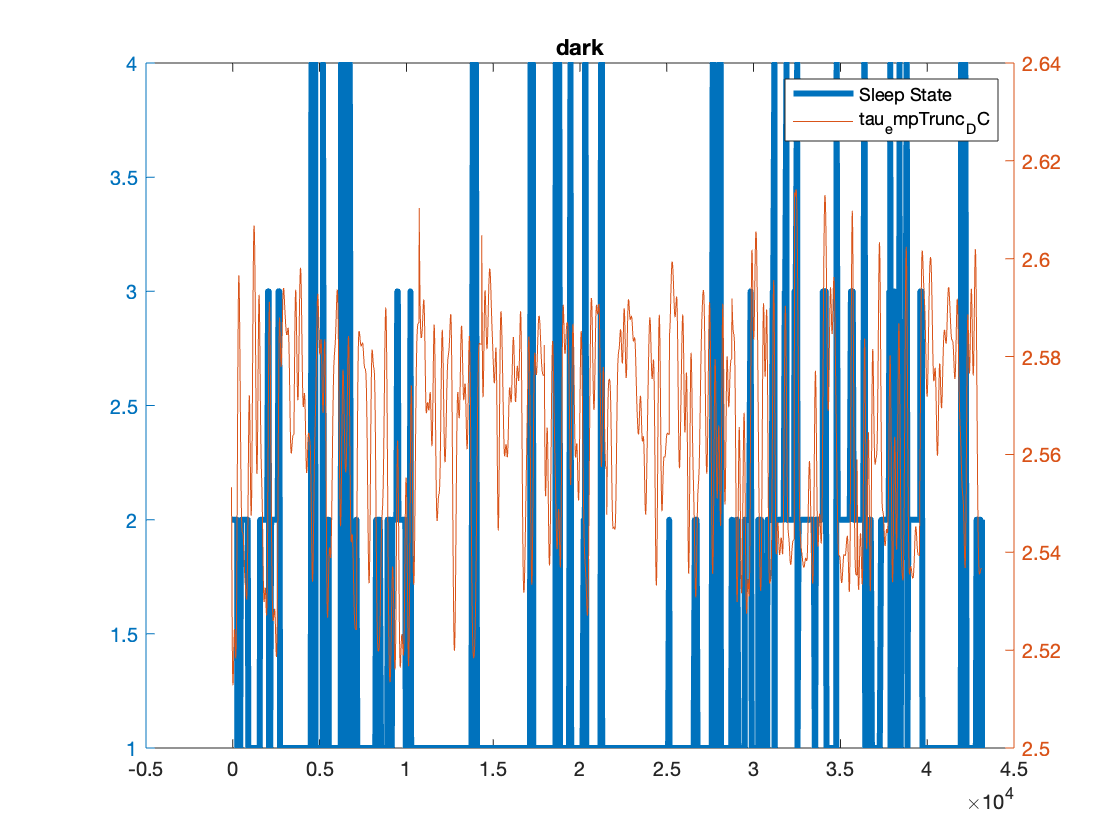


figure
yyaxis left
plot(time_z_all_darkonly, states_for_time_all_dark, 'lineWidth', 3)

yyaxis right
plot(time_z_all_darkonly, tau_empTrunc_all_DC_darkonly, 'lineWidth', 0.5)

title('dark')
legend('Sleep State','tau_empTrunc_DC')

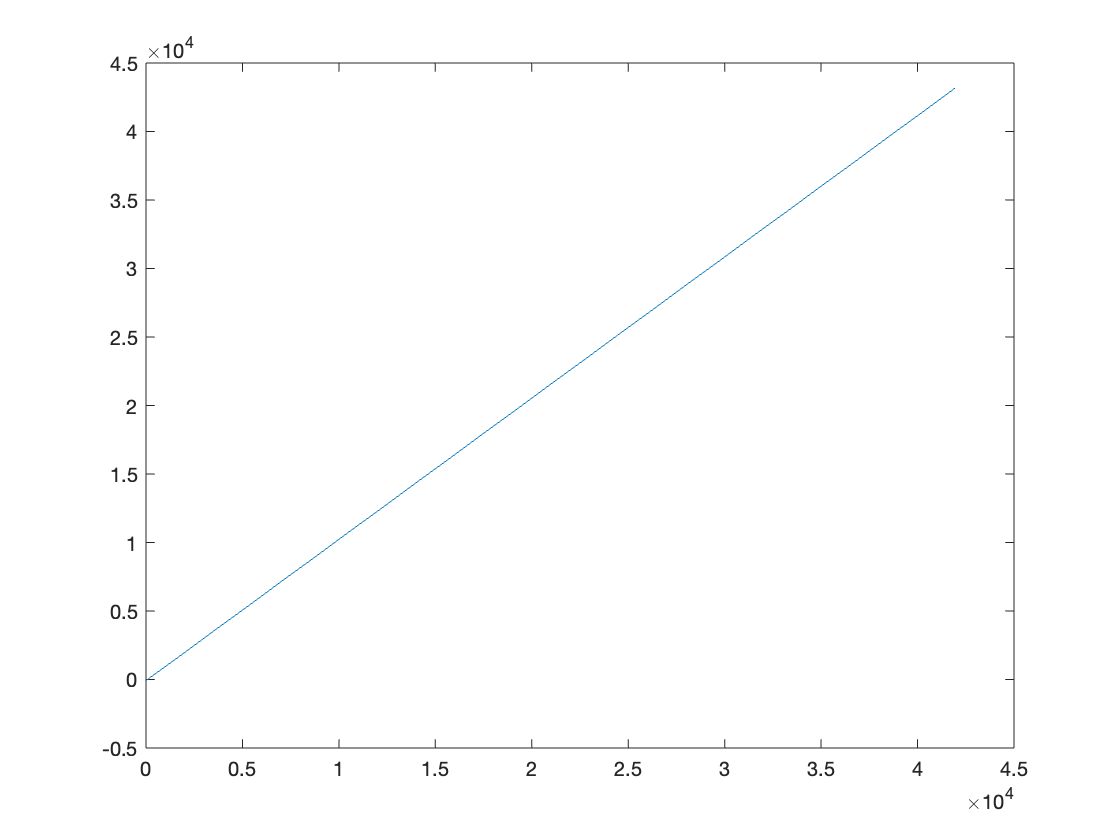


figure
plot(time_z_all_darkonly)


mkdir([analysis_name,'csv'])

csv_name=[analysis_name,'csv/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)




    
